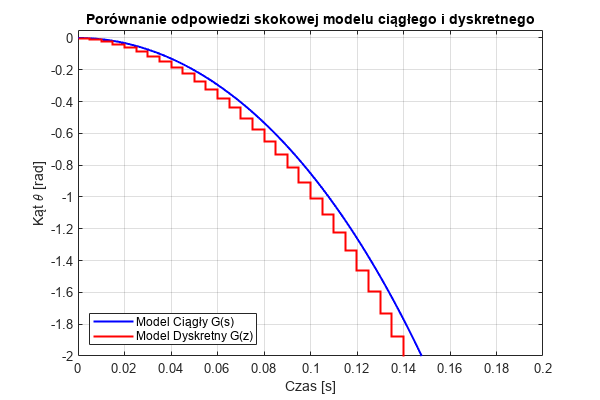

% =========================================================================
% PLIK: porownanie_modeli.m
% Opis: Tworzy transmitancje i porównuje model ciągły z dyskretnym
% =========================================================================

% 1. Wczytaj parametry (jeśli nie są wczytane)
if ~exist('a4', 'var')
    parametry_robota;
end

% === 2. MODEL CIĄGŁY G_simp(s) ===
% G(s) = b2 / (a4*s^2 + 0*s + a2)
Licznik_s = [b2];
Mianownik_s = [a4, 0, a2];

Gs = tf(Licznik_s, Mianownik_s);
Gs.InputName = 'u';
Gs.OutputName = 'theta';

% === 3. MODEL DYSKRETNY G_d(z) - METODA EULERA WSTECZNEGO ===
% Zgodnie z wyprowadzonym wzorem:
% G_d(z) = (Q0 * z^2) / (W * z^2 - P1 * z - P2)

% Obliczenie współczynników równania różnicowego
W  = a4 + a2 * Ts^2;
P1 = 2 * a4;
P2 = -a4;
Q0 = b2 * Ts^2;

% Tworzenie transmitancji dyskretnej
Licznik_z = [Q0, 0, 0];      % Q0*z^2
Mianownik_z = [W, -P1, -P2]; % W*z^2 - P1*z - P2

Gz_euler = tf(Licznik_z, Mianownik_z, Ts);

% (Opcjonalnie) Dla porównania automatyczna metoda Tustina z Matlaba
Gz_tustin = c2d(Gs, Ts, 'tustin'); 

% === 4. PORÓWNANIE I WYKRESY ===
figure(1);

T_plot = 0.2;

% Pobieramy dane dla modelu ciągłego
[y_c, t_c] = step(Gs, T_plot);

% Pobieramy dane dla modelu dyskretnego
[y_d, t_d] = step(Gz_euler, T_plot);

% Wykres A: Odpowiedź skokowa (Step Response)
% UWAGA: Układ jest niestabilny, więc wykresy szybko uciekną do nieskończoności.
% Ograniczamy czas symulacji do np. 0.5 sekundy, żeby zobaczyć początek.
set(gcf, 'Position', [100, 100, 600, 400]);
plot(t_c, y_c, 'b', 'LineWidth', 1.5); 
hold on;

% Rysujemy model dyskretny (czerwone schodki - to ważne dla dyskretnego!)
stairs(t_d, y_d, 'r', 'LineWidth', 1.5);
title('Porównanie odpowiedzi skokowej modelu ciągłego i dyskretnego');
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
legend('Model Ciągły G(s)', 'Model Dyskretny G(z)', 'Location', 'SouthWest');
xlim([0, 0.2]);
ylim([-2, 0.05]);
grid on;
hold off;
print('Odp_skok_G.png', '-dpng', '-r400');

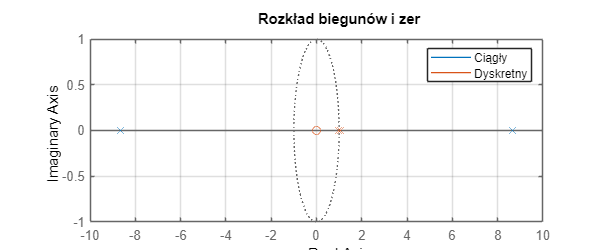


% Wykres B: Mapa biegunów i zer (Pole-Zero Map)
% Pokaże, czy biegun niestabilny (prawa półpłaszczyzna)
% przeszedł poprawnie poza okrąg jednostkowy w "Z".
figure('Position', [100, 100, 600, 250]);
pzmap(Gs, Gz_euler);
title('Rozkład biegunów i zer');
legend('Ciągły', 'Dyskretny');
grid on;
print('RozkladBieg_G.png', '-dpng', '-r400');


% Wypisanie transmitancji w terminalu
disp('--- Transmitancja Ciągła G(s) ---');

--- Transmitancja Ciągła G(s) ---


Gs

Gs =
 
  From input "u" to output "theta":
         -5.5
  -------------------
  0.03438 s^2 - 2.575
 
Continuous-time transfer function.



disp('--- Transmitancja Dyskretna G(z) [Twoja metoda Eulera] ---');

--- Transmitancja Dyskretna G(z) [Twoja metoda Eulera] ---


Gz_euler

Gz_euler =
 
           -0.0001375 z^2
  ---------------------------------
  0.03431 z^2 - 0.06875 z + 0.03438
 
Sample time: 0.005 seconds
Discrete-time transfer function.

